# Sistemas de Visión Artificial

# **Práctica 2. Técnicas Básicas de Procesamiento de Imágenes**

**Autor(es): Paula Fernández Sánchez, Luis Ramos Triguero, María Díez Martínez**

**Fecha:16-10-2026**

El objetivo de esta práctica es aplicar y analizar algunas de las técnicas básicas de procesamiento de imágenes estudiadas en teoría utilizando la **Image Processing Toolbox de MATLAB**. Se trabajará con transformaciones de intensidad, procesamiento basado en el histograma, transformaciones geométricas, interpolación, generación y reducción de ruido y filtrado espacial.

En la mayoría de los ejercicios se utilizarán imágenes de intensidad (escala de grises). Cuando se trabaje con imágenes en color deberá tenerse en cuenta su representación y decidir, en función de la operación que se quiera realizar, si conviene procesar directamente la imagen RGB o trabajar sobre alguna de sus componentes. Para realizar los ejercicios pueden utilizarse inicialmente las imágenes disponibles en el Aula Virtual. También pueden utilizarse otras imágenes, siempre que cumplan las características requeridas en cada apartado: imagen RGB o indexada, de bajo contraste, oscura, etc. 

Antes de procesar una imagen es importante comprobar tanto su **tipo de representación** —RGB, indexada, escala de grises o binaria— como su **clase de datos** (`uint8`, `uint16`, `single`, `double`, `logical`, etc.). La clase determina, entre otras cosas, el rango numérico de los niveles de intensidad y puede condicionar el comportamiento de algunas operaciones. Esto es especialmente importante cuando en los ejercicios no se indica qué conversión debe realizarse o cuando se utilizan imágenes diferentes a las inicialmente indicadas en el enunciado. Si una imagen no tiene la representación o clase de datos adecuados, algunas funciones pueden producir un error —indicando, en ocasiones, el tipo de datos esperado— o proporcionar un resultado inesperado. En cualquiera de los dos casos deberá comprobarse qué tipo de entrada espera la función y realizar, si es necesario, la conversión adecuada.

**La práctica se completará en este mismo fichero .mlx**, incluyendo el nombre del autor o autores del grupo, la fecha, el código y los comentarios y conclusiones pertinentes en cada apartado. Los distintos apartados deberán estar separados en **secciones independientes** mediante un *section break*. En el código, una nueva sección se introduce escribiendo `%%`, aunque también puede añadirse mediante la opción correspondiente del menú. Cree una nueva figura para cada grupo de resultados que deba mostrarse conjuntamente. Cuando sea necesario comparar varias imágenes, utilice `subplot` o `tiledlayout` y `nexttile`. De esta forma se evita que las imágenes correspondientes a distintos apartados se superpongan o aparezcan asociadas a secciones posteriores.

De cara a facilitar el aprendizaje y la preparación de los test de laboratorio, se recomienda ampliar la práctica con las explicaciones oportunas, realizar pruebas adicionales (modificando parámetros o utilizando otras imágenes que permitan apreciar mejor determinados efectos del procesamiento) y describir los problemas encontrados durante su realización y las soluciones adoptadas.

Esta práctica no consiste únicamente en obtener las imágenes solicitadas. Es especialmente importante realizar una **correcta interpretación de los resultados**, justificar los parámetros utilizados y llevar a cabo las pruebas adicionales que resulten necesarias para comprender el efecto de las distintas operaciones.

La entrega se realizará en el Aula Virtual de la asignatura: **Contenidos → Entregables → Práctica 2**.

Implemente el siguiente código, visualice los resultados obtenidos y justifíquelos:

**1.** Abra y visualice al menos dos imágenes en color: una RGB y otra indexada. Determine previamente el tipo de cada imagen utilizando `imfinfo` y consultando el campo `ColorType.` Observe también sus dimensiones, profundidad de bits y clase de datos una vez cargadas en MATLAB.

Cargue cada imagen utilizando las variables necesarias para conservar correctamente su representación (`I`, `X`, `map`, etc.) y visualícelas en figuras independientes (evitando, en este caso, el comando *subplot*).

Explique brevemente las diferencias entre la representación RGB y la representación indexada. 

clear all
close all

infoRGB = imfinfo('football.jpg');
infoRGB.ColorType  %que tipo de imagen es

ans = 'truecolor'

infoRGB.BitDepth   %cuantos bits usa cada pixel

ans = 24

infoIND = imfinfo('kids.tif');
infoIND(1).ColorType      

ans = 'indexed'

infoIND(1).BitDepth

ans = 8

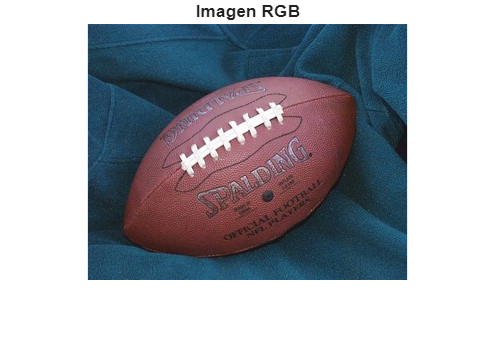

I = imread('football.jpg');       % Al ser una imagen RGB cargamos la matriz directamente
[X, map] = imread('kids.tif');    % Al ser una imagen indexada: le pasamos índices y luego el mapa de color

figure, imshow(I); title('Imagen RGB');

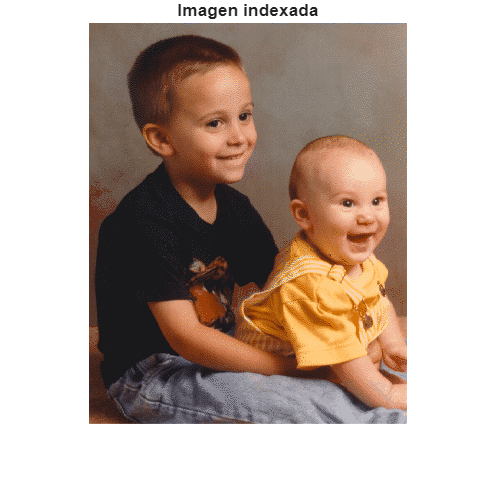

figure, imshow(X, map); title('Imagen indexada');

% La diferencia que hemos podido observar es la forma en la que se guardan
% los datos de la imagen en RGB es un MxNx3 y en la indexada es una MxN mas
% un mapa Kx3

2. Convierta la imagen indexada anterior a escala de grises y denomine `Igris` a la imagen resultante.

Igris = ind2gray(X, map);

 Sobre `Igris`:

    2.1 Realice:

- una modificación de **brillo**;

- una modificación de **contraste**.

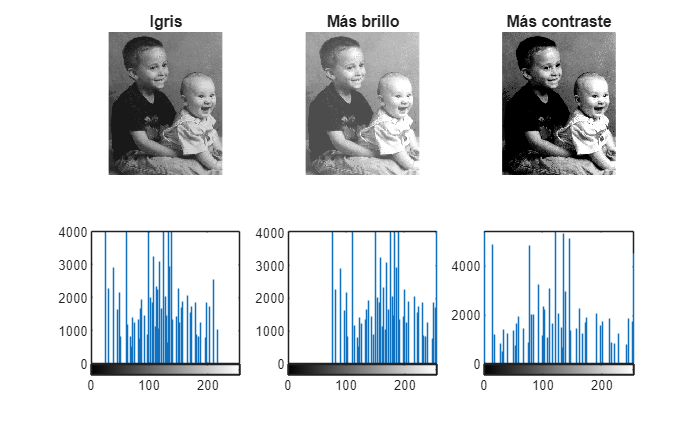

Ibrillo = imadjust(Igris, [0 0.8], [0.2 1]);
Icontraste = imadjust(Igris, [0.2 0.8], [0 1]);

figure
subplot(2,3,1)
imshow(Igris);
title('Igris');
subplot(2,3,2)
imshow(Ibrillo);
title('Más brillo');
subplot(2,3,3)
imshow(Icontraste);
title('Más contraste');
subplot(2,3,4)
imhist(Igris);
subplot(2,3,5)
imhist(Ibrillo);
subplot(2,3,6)
imhist(Icontraste);

Muestre `Igris` y las imágenes resultantes, junto con sus histogramas. Indique las transformaciones utilizadas, los intervalos inicial y final y justifique, a partir de ellas y de los histogramas, por qué en un caso se modifica el brillo y en el otro el contraste.

    2.2 Umbralice `Igris` utilizando `imbinarize`. Muestre la imagen binaria y su histograma. Pruebe con diferentes umbrales y observe la relación del valor del umbral con las imágenes resultantes.

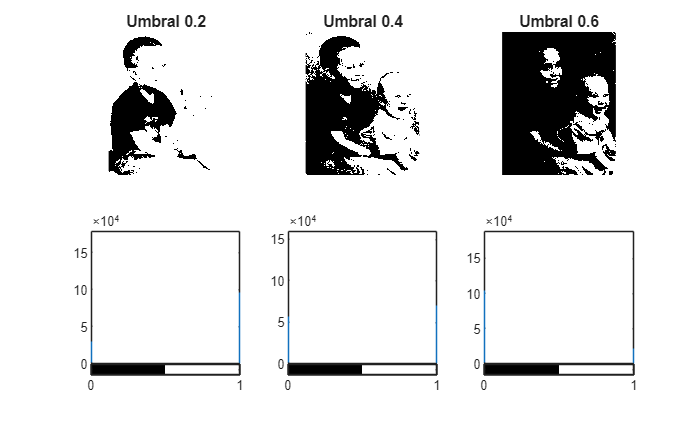

Igris = ind2gray(X, map);

BW1 = imbinarize(Igris, 0.2);
BW2 = imbinarize(Igris, 0.4);
BW3 = imbinarize(Igris, 0.6);

figure
subplot(2,3,1)
imshow(BW1);
title('Umbral 0.2');
subplot(2,3,2)
imshow(BW2);
title('Umbral 0.4');
subplot(2,3,3)
imshow(BW3);
title('Umbral 0.6');
subplot(2,3,4)
imhist(BW1);
subplot(2,3,5)
imhist(BW2);
subplot(2,3,6)
imhist(BW3);

   2.3 Obtenga el negativo de `Igris`. Muestre conjuntamente la imagen original y el negativo, así como sus histogramas. Explique la relación entre ambos histogramas.

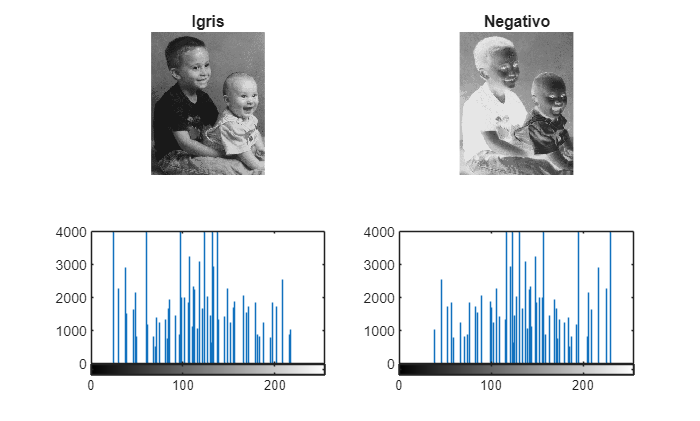

Ineg = imadjust(Igris, [0 1], [1 0]);

figure
subplot(2,2,1)
imshow(Igris);
title('Igris');
subplot(2,2,2)
imshow(Ineg);
title('Negativo');
subplot(2,2,3)
imhist(Igris);
subplot(2,2,4)
imhist(Ineg);

3. Sobre la imagen "avion1.jpg":

    3.1 Realice una corrección gamma. Pruebe con distintos valores de gamma (al menos un valor de gamma < 1 y otro > 1) y analice el efecto de cada uno sobre la imagen de salida.

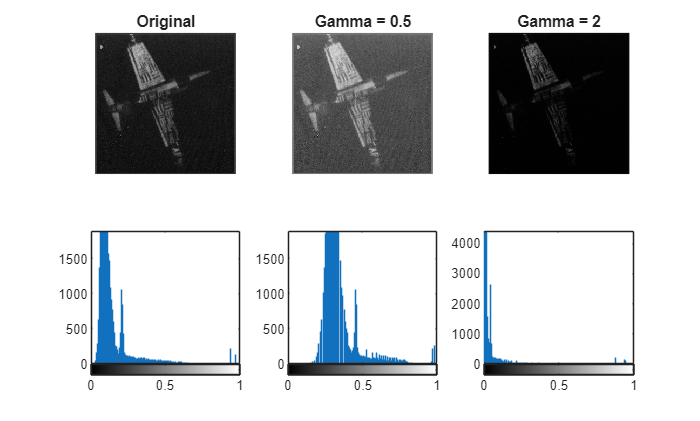

Ia = imread('avion1.jpg');
Ia = im2gray(Ia);
Ia = im2double(Ia);

G1 = imadjust(Ia, [], [], 0.5); %Con ganma menor de 1 la imagen se aclara
G2 = imadjust(Ia, [], [], 2); %Con ganma mayor de 1 la imagen se oscurece

figure
subplot(2,3,1)
imshow(Ia);
title('Original');
subplot(2,3,2)
imshow(G1);
title('Gamma = 0.5'); 
subplot(2,3,3)
imshow(G2);
title('Gamma = 2');
subplot(2,3,4)
imhist(Ia);
subplot(2,3,5)
imhist(G1);
subplot(2,3,6)
imhist(G2);

3.2 Ecualice el histograma de la imagen utilizando `histeq` con 256, 64 y 8 niveles de salida. Muestre conjuntamente la imagen original y las tres imágenes obtenidas, junto con sus histogramas. Compare los resultados y explique cómo influye el número de niveles utilizado en la ecualización.

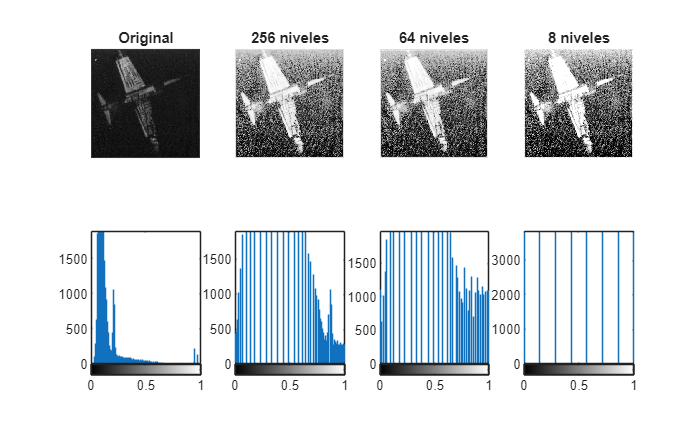

E256 = histeq(Ia, 256); %El primer parametro es la imagen que quiero ecualizar, y el segundo parametro es el numero de niveles de gris de la imagen
E64 = histeq(Ia, 64);
E8 = histeq(Ia, 8);

figure
subplot(2,4,1)
imshow(Ia);
title('Original');
subplot(2,4,2)
imshow(E256);
title('256 niveles');
subplot(2,4,3)
imshow(E64);
title('64 niveles');
subplot(2,4,4)
imshow(E8);
title('8 niveles');
subplot(2,4,5)
imhist(Ia);
subplot(2,4,6)
imhist(E256);
subplot(2,4,7)
imhist(E64);
subplot(2,4,8)
imhist(E8);

4. Sobre la imagen "matricula.jpg":

    4.1 Averigüe sus dimensiones (filas x columnas) en píxeles. Obtenga una nueva imagen con la mitad de filas y la mitad de columnas y verifique su tamaño. Visualice ambas figuras. Para poder ver el cambio de tamaño puede utilizar la instrucción *truesize *después de *imshow *para que las imágenes no ajusten su tamaño al de la ventana.

Im = imread('matricula.jpg');
infoRGB = imfinfo('matricula.jpg');
infoRGB.ColorType  %que tipo de imagen es para saber si pido tambien profunidad_color o no

ans = 'truecolor'

Im = imread('matricula.jpg');
[filas, columnas, profundidad_color] = size(Im)

filas = 187

columnas = 500

profundidad_color = 3


Im2 = imresize(Im, 0.5);
size(Im2)

ans =     94   250     3


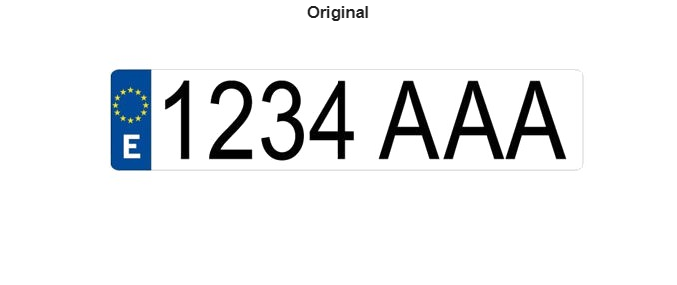

figure
imshow(Im);
truesize;
title('Original');

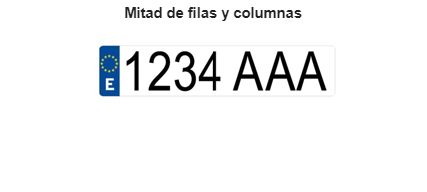

figure
imshow(Im2);
truesize;
title('Mitad de filas y columnas');

 4.2 Rote la imagen un ángulo de 65,3º utilizando los métodos de interpolación `nearest` y `bicubic`. Muestre la imagen original y ambos resultados conjuntamente. Amplíe una zona con bordes o detalles finos para hacer visibles las diferencias entre los dos métodos y explíquelas.

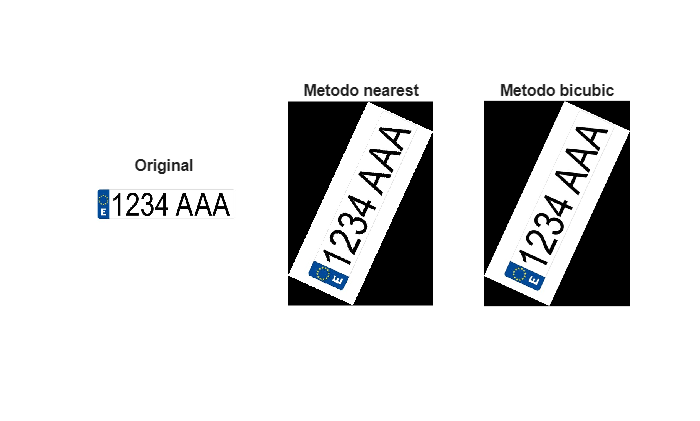

Irn = imrotate(Im, 65.3, 'nearest');
Irb = imrotate(Im, 65.3, 'bicubic');

figure
subplot(1,3,1)
imshow(Im);
title('Original');
subplot(1,3,2)
imshow(Irn);
title('Metodo nearest');
subplot(1,3,3)
imshow(Irb);
title('Metodo bicubic');

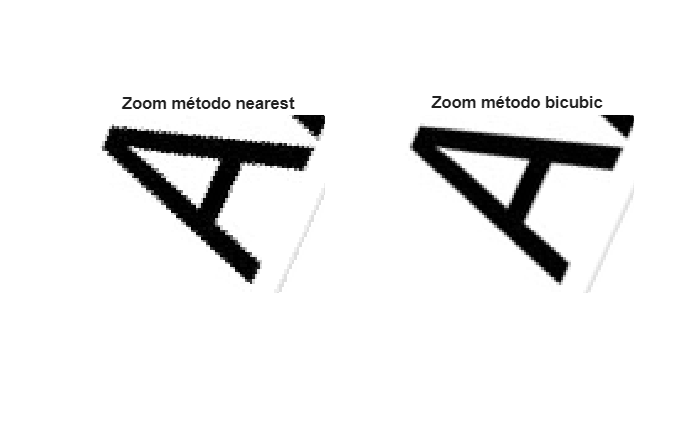


figure
subplot(1,2,1)
imshow(Irn);
title('Zoom método nearest'); %Los bordes de la A salen escalonados, porque cada píxel copia al "vecino" más cercano
subplot(1,2,2)
imshow(Irb);
title('Zoom método bicubic'); %Los bordes de la A salen suaves, porque cada píxel es una mezcla ponderada de los de alrededor.

subplot(1,2,1)  %Dentro de la imagen nearest
xlim([180 275]) %Segundo parametro de las dimensiones
ylim([178 250]) %Primer parametro de las dimensiones

subplot(1,2,2)  %Dentro de la imagen bicubic
xlim([180 275])
ylim([178 250])

5. Ruido y filtrado

5.1. A partir de la imagen `cell.tif`, obtenga y muestre una versión con ruido gaussiano de media cero y varianza 0,01, que denominaremos `Ig`. Fíltrela utilizando un filtro de promedio del entorno de vecindad, primero con un entorno de 3x3 y después con uno de 5x5. Muestre conjuntamente la imagen original, la imagen ruidosa y las dos imágenes filtradas, utilizando `subplot` o `tiledlayout`/`nexttile`. Compare los resultados y justifique el efecto que tiene el tamaño del entorno sobre la reducción de ruido y la conservación de los detalles de la imagen.

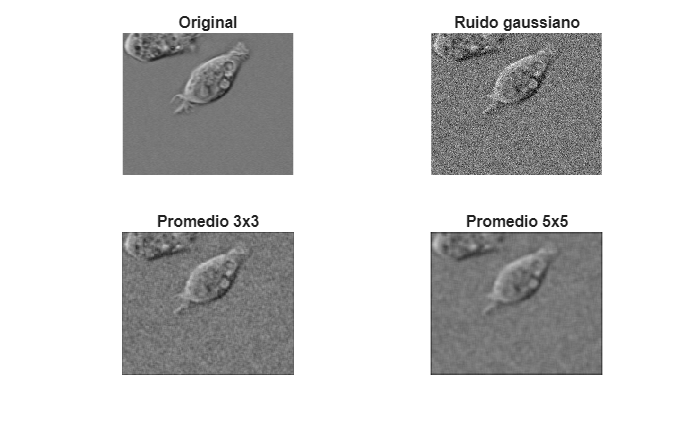

Ic = imread('cell.tif');
Ic = im2double(Ic);

Ig = imnoise(Ic, 'gaussian', 0, 0.01);

h3 = fspecial('average', 3);
h5 = fspecial('average', 5);
K3 = filter2(h3, Ig);
K5 = filter2(h5, Ig);

figure
subplot(2,2,1)
imshow(Ic);
title('Original');
subplot(2,2,2)
imshow(Ig);
title('Ruido gaussiano');
subplot(2,2,3)
imshow(K3);
title('Promedio 3x3');
subplot(2,2,4)
imshow(K5);
title('Promedio 5x5');

5.2. Obtenga una versión de `cell.tif` con ruido de tipo sal y pimienta de densidad 5 %. Fíltrela utilizando un filtro de mediana y un filtro paso bajo de promedio del entorno de vecindad con entorno 3x3. Muestre conjuntamente la imagen original, la imagen ruidosa y las dos imágenes filtradas. Compare los resultados y responda: ¿qué tipo de filtrado resulta más adecuado para este tipo de ruido? Justifique sus conclusiones teniendo en cuenta tanto la eliminación del ruido como la conservación de bordes y detalles.

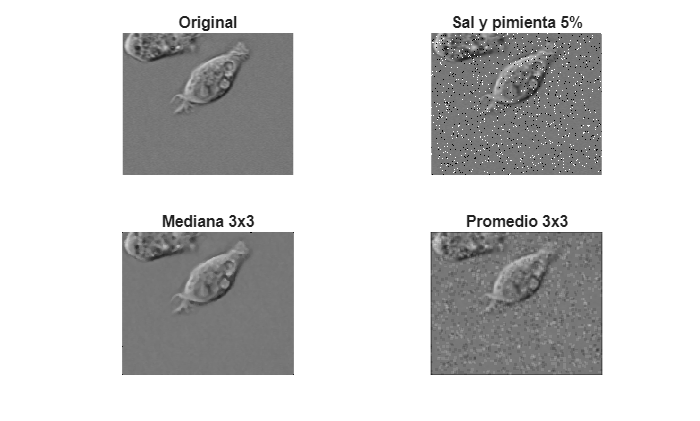

Isp = imnoise(Ic, 'salt & pepper', 0.05);

L = medfilt2(Isp, [3 3]);
h3 = fspecial('average', 3);
K = filter2(h3, Isp);

figure
subplot(2,2,1)
imshow(Ic);
title('Original');
subplot(2,2,2)
imshow(Isp);
title('Sal y pimienta 5%');
subplot(2,2,3)
imshow(L);
title('Mediana 3x3');
subplot(2,2,4)
imshow(K);
title('Promedio 3x3');

5.3. Obtenga y muestre una versión de `cell.tif` con ruido multiplicativo de tipo *speckle *con varianza 0.05. Fíltrela utilizando un filtro de Wiener y un filtro paso bajo de promedio  del entorno de vecindad con entorno 5x5. Muestre conjuntamente la imagen original, la imagen ruidosa y las dos imágenes filtradas. Compare los resultados y responda: ¿cuál de los dos filtros resulta más adecuado para este tipo de ruido? Justifique su respuesta teniendo en cuenta la reducción del ruido y la conservación de los detalles de la imagen.

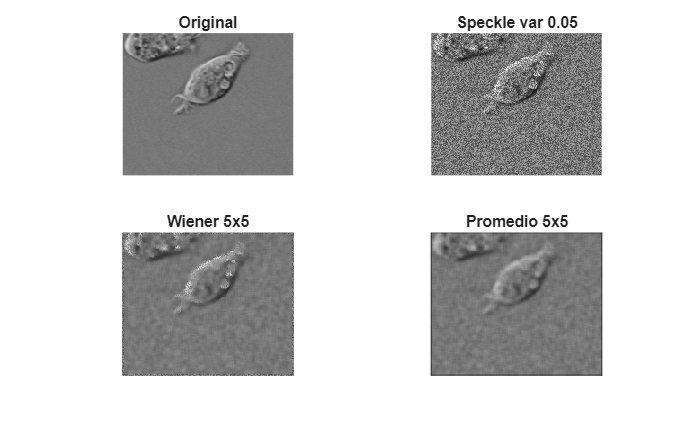

Isk = imnoise(Ic, 'speckle', 0.05);

W = wiener2(Isk, [5 5]);
h5 = fspecial('average', 5);
K = filter2(h5, Isk);

figure
subplot(2,2,1)
imshow(Ic);
title('Original');
subplot(2,2,2)
imshow(Isk);
title('Speckle var 0.05');
subplot(2,2,3)
imshow(W);
title('Wiener 5x5');
subplot(2,2,4)
imshow(K);
title('Promedio 5x5');

5.4. Mediante un bucle `for`, obtenga 32 imágenes diferentes a partir de `cell.tif`, añadiendo a cada una ruido gaussiano independiente de media cero y varianza 0,05. Guarde las imágenes utilizando `imwrite` en ficheros con nombres consecutivos (`ruidosa1.bmp`, …, `ruidosa32.bmp`). Puede generar los nombres de los ficheros dentro del bucle *for* utilizando, por ejemplo: "ruidosa" + i + ".bmp".

A continuación, aplique la técnica de promediado de imágenes, utilizando primero 4 imágenes ruidosas, después 8, 16 y, finalmente, las 32 imágenes. Muestre conjuntamente la imagen original, una de las imágenes ruidosas y los resultados obtenidos al promediar 4, 8, 16 y 32 imágenes. Compare visualmente los resultados y explique cómo evoluciona el ruido de la imagen de salida al aumentar el número de imágenes promediadas. Preste especial atención al tipo de datos utilizado durante el cálculo del promedio, para evitar pérdidas de precisión o saturaciones.

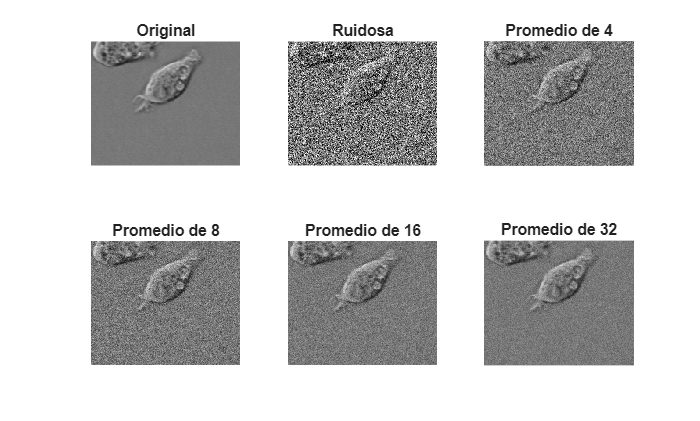

for i = 1:32
    J = imnoise(Ic, 'gaussian', 0, 0.05);
    nombre = "ruidosa" + i + ".bmp";
    imwrite(J, nombre);
end

suma = zeros(size(Ic));

for i = 1:4
    nombre = "ruidosa" + i + ".bmp";
    R = imread(nombre);
    R = im2double(R);
    suma = suma + R;
end
P4 = suma/4;

for i = 5:8
    nombre = "ruidosa" + i + ".bmp";
    R = imread(nombre);
    R = im2double(R);
    suma = suma + R;
end
P8 = suma/8;

for i = 9:16
    nombre = "ruidosa" + i + ".bmp";
    R = imread(nombre);
    R = im2double(R);
    suma = suma + R;
end
P16 = suma/16;

for i = 17:32
    nombre = "ruidosa" + i + ".bmp";
    R = imread(nombre);
    R = im2double(R);
    suma = suma + R;
end
P32 = suma/32;

R1 = imread("ruidosa1.bmp");

figure
subplot(2,3,1)
imshow(Ic);
title('Original');
subplot(2,3,2)
imshow(R1);
title('Ruidosa');
subplot(2,3,3)
imshow(P4);
title('Promedio de 4');
subplot(2,3,4)
imshow(P8);
title('Promedio de 8');
subplot(2,3,5)
imshow(P16);
title('Promedio de 16');
subplot(2,3,6)
imshow(P32);
title('Promedio de 32');